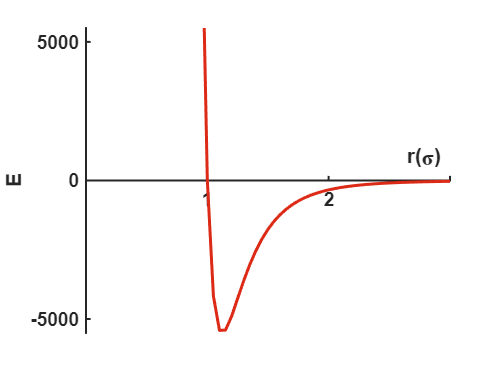

%给出势能函数E和对映的概率密度分布P
clear all
syms e r o;

y1=[];
y2=[];

hold on
axis([0 3 -5500 5500]);

%势能函数E
e=5500;
o=1;
for r=0.5:0.05:3
    E=4*e*(((o/r)^12)-((o/r)^6));
    y1=[y1,E];
end
x1=[0.5:0.05:3];
plot(x1,y1,'LineWidth',1.5, ...
    'color',[221, 42, 22]/256)
ax = gca;
ax.XAxisLocation = 'origin';
ax.YAxisLocation = 'origin';

set(gca,'linewidth',1,'FontWeight','bold','FontName','arial');
xlabel('r(\sigma)','FontName','arial','FontWeight','bold'); 
ylabel('E','FontName','arial','FontWeight','bold');

hold off

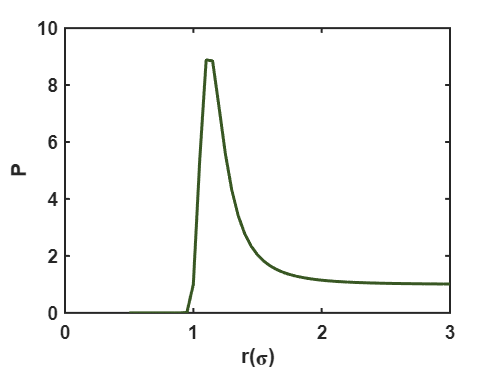



%概率分布函数P
for r=0.5:0.05:3
    E=4.*e.*(((r/o).^(-12))-((r/o).^(-6)));
    P=exp(-E/(8.31*298));
    y2=[y2,P];
end
x2=[0.5:0.05:3];
plot(x2,y2,'LineWidth',1.5, ...
    'color',[56, 87, 35]/256)
xlim([0 3])
ylim([0 10])

set(gca,'linewidth',1,'FontWeight','bold','FontName','arial');
xlabel('r(\sigma)','FontName','arial','FontWeight','bold'); 
ylabel('P','FontName','arial','FontWeight','bold');